# Exercise 1: Bacterial growth curve

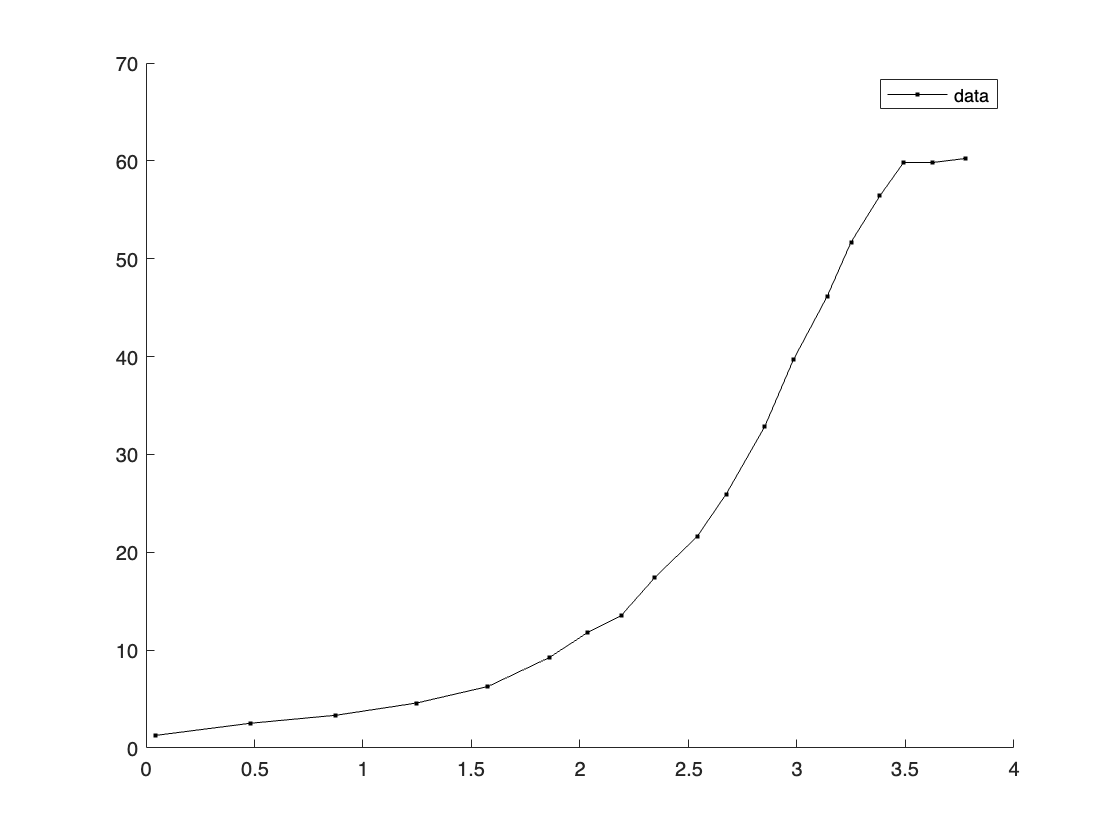

% From Wiki "Diauxie" reproduced from Monod's PhD thesis
% Bacterial growth (E. coli) on glucose and fructose

% Data
% Time (hours)		Optical density (proportional to mass)
x = [0.04406743301915	1.285584146987
0.48156559689	2.528863914313
0.875231685788	3.346749281098
1.247158005598	4.597079784344
1.575487274965	6.282205669359
1.860454518421	9.262316718449
2.036017842843	11.82408410292
2.189488861381	13.52801195039
2.343547441245	17.38241425363
2.541438096082	21.66221095741
2.673756906858	25.94905839711
2.850495353933	32.81177469313
2.983519238301	39.67919147975
3.138282891758	46.11416312992
3.249096957976	51.69364548839
3.381533281017	56.41058781925
3.491759785908	59.83959572195
3.622903474031	59.8254942501
3.776021955772	60.23913742411];
% Note: there is an offset on the OD (i.e. it does not necessarily start at OD=0)

p = [];

%plot the data
t = x(:,1);
od = x(:,2);
figure; hold on;
p(1) = plot(t,od,'k.-', 'DisplayName', 'data'); legend(p);

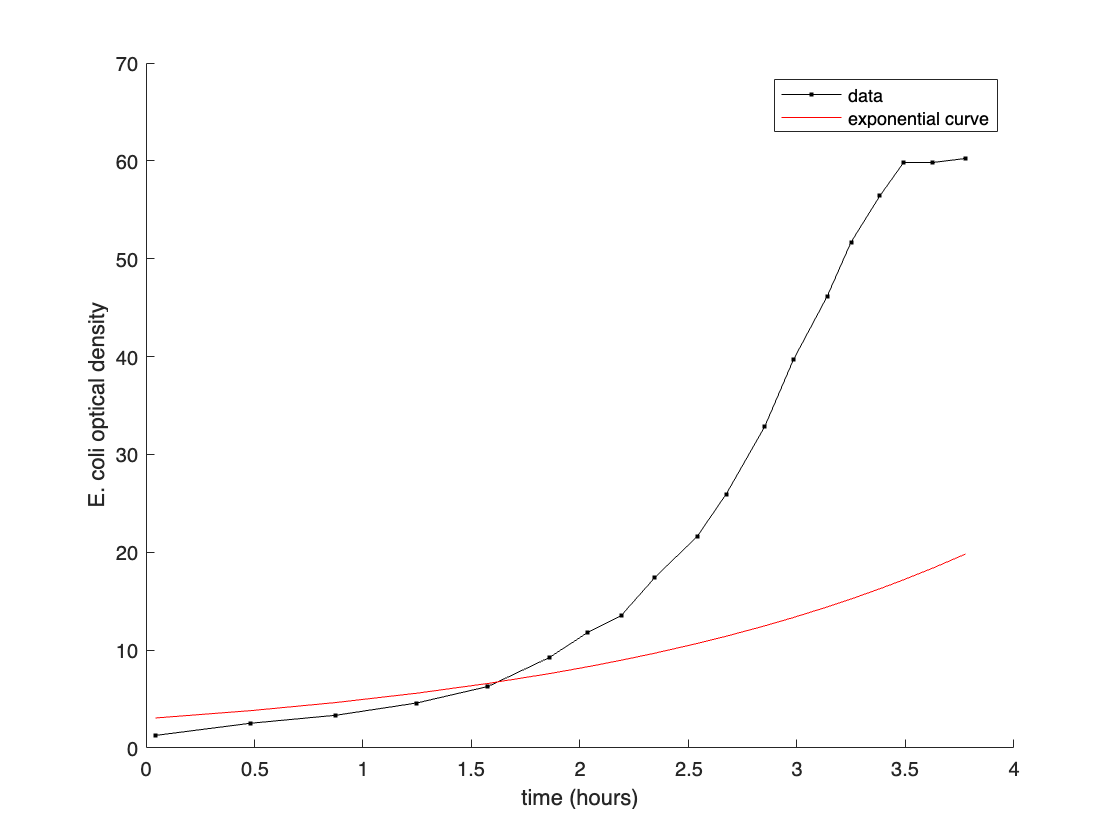

% Fit this data to an exponential curve
% You need to find an exponential function (with starting value f0 and time
% constant tau) that gives a "good" fit by eye. Just play with the
% parameters until you get something that looks OK.

% Here is a first guess

f0=3;
tau=2;
f = f0*exp(t/tau);
p(2) = plot(t,f,'r-', 'DisplayName', 'exponential curve');

xlabel('time (hours)');
ylabel('E. coli optical density');
legend(p);

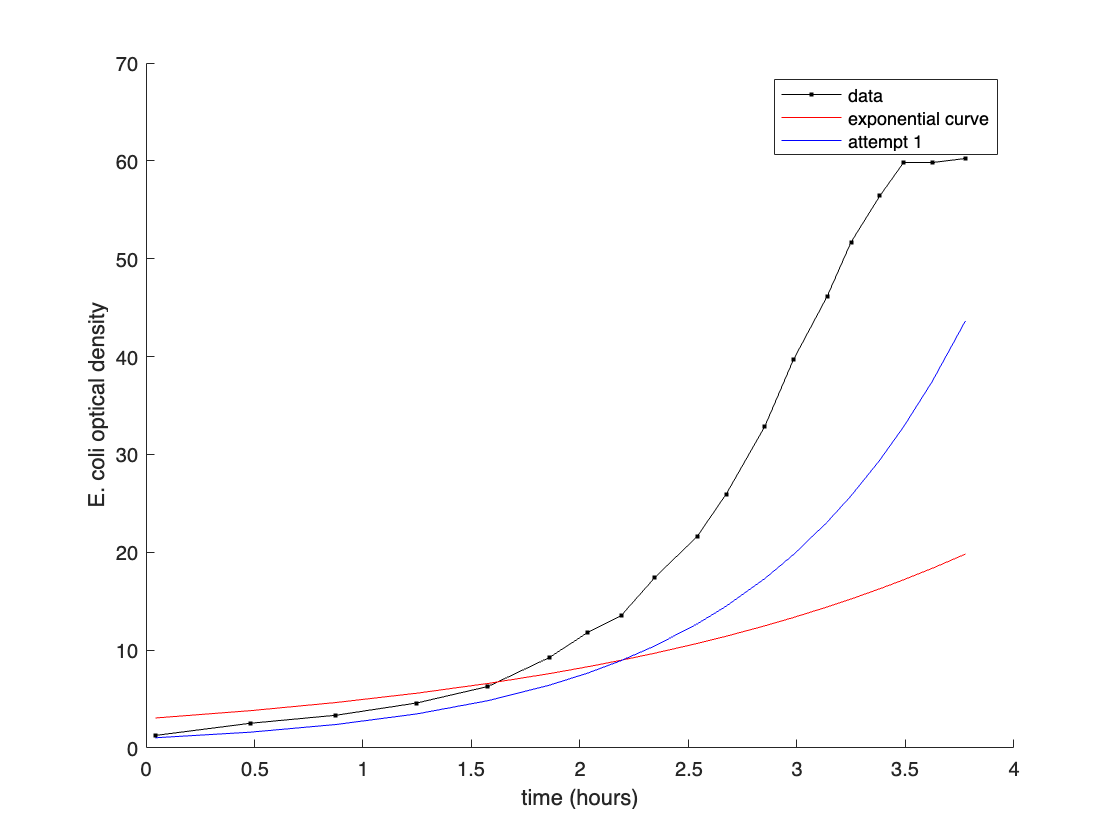

% The starting value clearly needs to be lower, and the rate of increase
% should be much faster; hence, tau must be lower.

f0=1;
tau=1;
f = f0*exp(t/tau);
p(3) = plot(t,f,'b-');

xlabel('time (hours)');
ylabel('E. coli optical density');
legend('data','exponential curve', 'attempt 1');

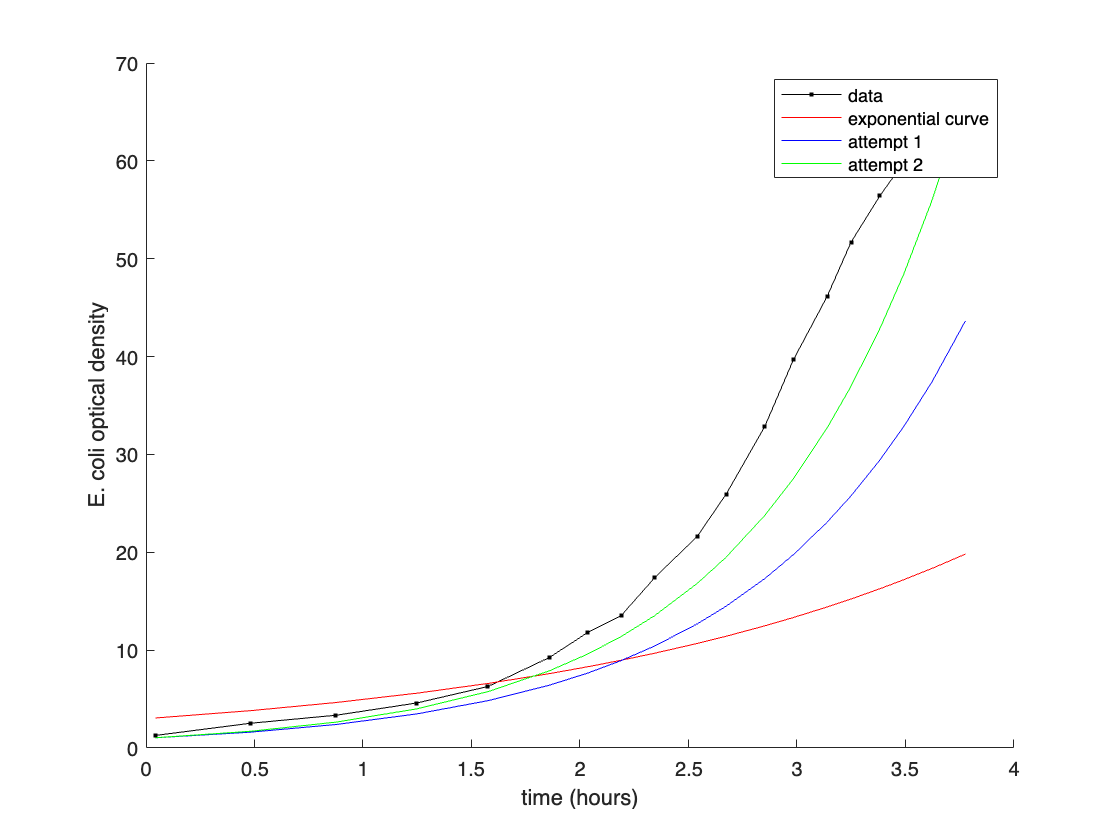

% tau needs to be decreased further.

f0=1;
tau=0.9;
f = f0*exp(t/tau);
p(4) = plot(t,f,'g-', 'DisplayName', 'attempt 2');

xlabel('time (hours)');
ylabel('E. coli optical density');
legend(p);

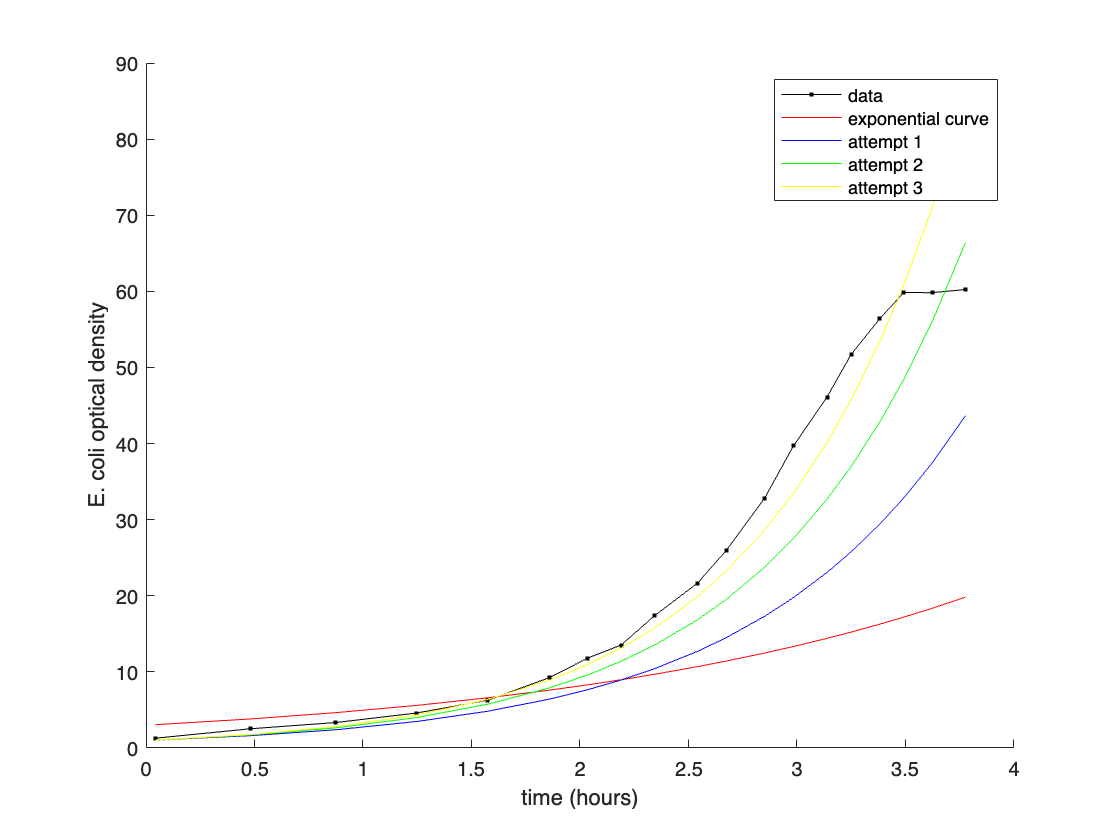

f0=1;
tau=0.85;
f = f0*exp(t/tau);
p(5) = plot(t,f,'y-', 'DisplayName', 'attempt 3');

xlabel('time (hours)');
ylabel('E. coli optical density');
legend(p);

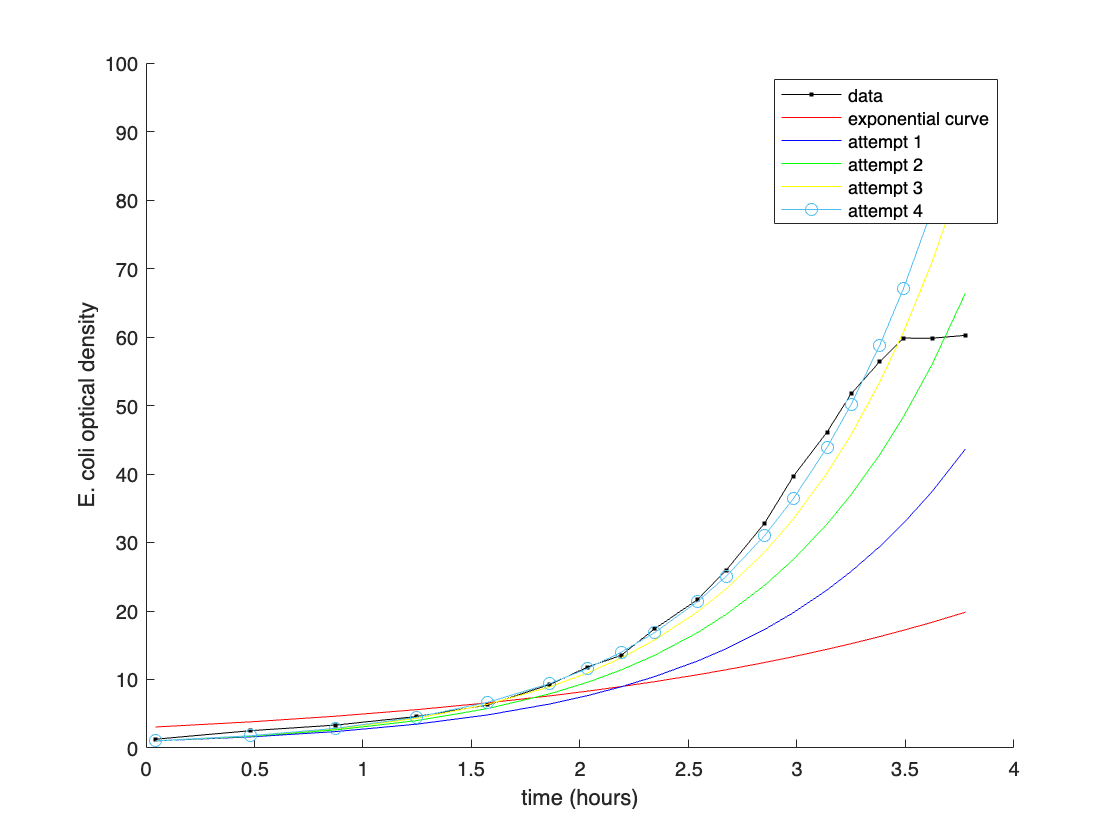

f0=1;
tau=0.83;
f = f0*exp(t/tau);
p(6) = plot(t,f,'o-', 'DisplayName', 'attempt 4');

xlabel('time (hours)');
ylabel('E. coli optical density');
legend(p);

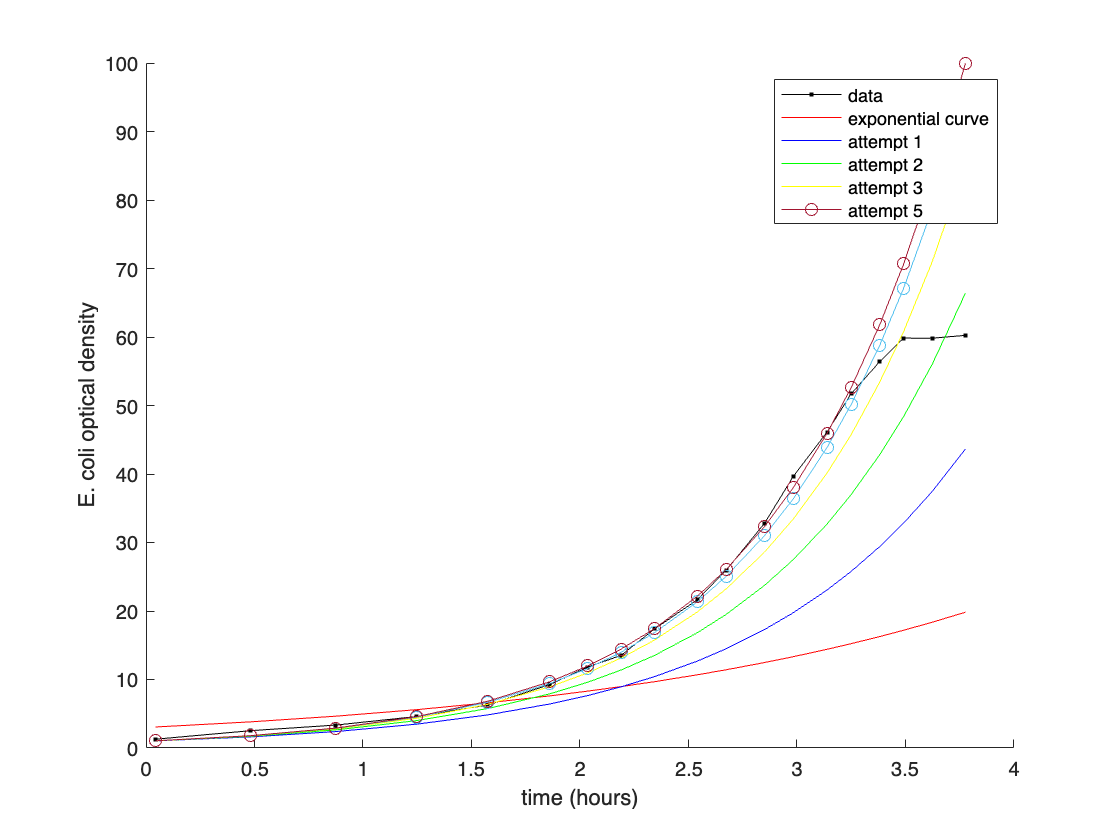

f0=1;
tau=0.82;
f = f0*exp(t/tau);
p(6) = plot(t,f,'o-', 'DisplayName', 'attempt 5');

xlabel('time (hours)');
ylabel('E. coli optical density');
legend(p);

#### Hence, the parameters -- f0=1 and tau=0.82 -- seem to be a good fit for the given data.